# Examination

## 1

8/12

ans = 0.6667

## 2

I = run_length(10,10,[3,4,4,5,5,6,7,7],[4,3,5,3,6,3,3,7;6,3,6,3,7,7,5,7])

I =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     1     1     0     0     0     0
     0     0     1     0     1     1     0     0     0     0
     0     0     1     0     0     1     1     0     0     0
     0     0     1     1     1     1     1     0     0     0
     0     0     1     1     1     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


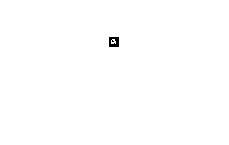

imshow(I)

se1 = strel('disk',1)

se1 = strel is a disk shaped structuring element with properties:

      Neighborhood: [3×3 logical]
    Dimensionality: 2


se2 = strel('square',3)

se2 = strel is a square shaped structuring element with properties:

      Neighborhood: [3×3 logical]
    Dimensionality: 2


I1 = imclose(I,se2)

I1 =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     1     1     0     0     0     0
     0     0     1     1     1     1     0     0     0     0
     0     0     1     1     1     1     1     0     0     0
     0     0     1     1     1     1     1     0     0     0
     0     0     1     1     1     1     1     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


I2 = imdilate(I1,se1)

I2 =      0     0     0     0     0     0     0     0     0     0
     0     0     0     1     1     1     0     0     0     0
     0     0     1     1     1     1     1     0     0     0
     0     1     1     1     1     1     1     0     0     0
     0     1     1     1     1     1     1     1     0     0
     0     1     1     1     1     1     1     1     0     0
     0     1     1     1     1     1     1     1     0     0
     0     0     1     1     1     1     1     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


I3 = I2-I

I3 =      0     0     0     0     0     0     0     0     0     0
     0     0     0     1     1     1     0     0     0     0
     0     0     1     0     0     0     1     0     0     0
     0     1     0     1     0     0     1     0     0     0
     0     1     0     1     1     0     0     1     0     0
     0     1     0     0     0     0     0     1     0     0
     0     1     0     0     0     1     0     1     0     0
     0     0     1     1     1     1     1     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


sum(sum(I3))

ans = 22

## 3

a1 = 3;a2=1;a3=4;b1=2;b2=7;b3=6;c1=2;c2=1;
x=10;y=30;
x1=(a1*x+a2*y+a3)/(c1*x+c2*y+1)

x1 = 1.2549

y1=(b1*x+b2*y+b3)/(c1*x+c2*y+1)

y1 = 4.6275

xx = [3,1,4;
    2,7,6;
    2,1,1]*[10;30;1]

xx =     64
   236
    51


xx(1)/xx(3)

ans = 1.2549

xx(2)/xx(3)

ans = 4.6275

## 4

A = rot(8)*[33;97]

A =    19.1791
  100.6487


x = A(1)

x = 19.1791

y=A(2)

y = 100.6487

v = blinliner(x,y,[143,98,197,213])

v = 177.0586

## 5

20*tand(14)

ans = 4.9866

## 6

I = run_length(10,10,[5,6,6,7,8]+1,[3,1,3,1,1;3,1,4,4,1]+1)

I =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0
     0     1     0     1     1     0     0     0     0     0
     0     1     1     1     1     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


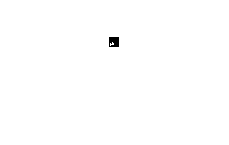

imshow(I)

## 7

I = chaincode([1,1]+1,[7,6,6,7,7,6,4,4,5,2,2,7,1,2,3,3,2,2])

I =      0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0
     0     1     1     0     0     0     0     0     0     0
     0     1     1     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0
     0     1     0     1     1     0     0     0     0     0
     0     1     1     1     1     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


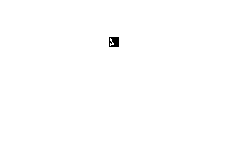

imshow(I)

## 8

r = [18,25,25;170,10,250;140,0,10]

r =     18    25    25
   170    10   250
   140     0    10


g = [10,75,90;30,150,10;20,20,20]

g =     10    75    90
    30   150    10
    20    20    20


b = [45,70,155;10,220,70;0,160,45]

b =     45    70   155
    10   220    70
     0   160    45


I = round((r+g+b)/3)

I =     24    57    90
    70   127   110
    53    60    25


II = remapping(I,20,180)

II =    20.0000   71.2621  122.5243
   91.4563  180.0000  153.5922
   65.0485   75.9223   21.5534


## 9

I = [193,180,98,112,125;
    189,8,177,97,114;
    100,71,81,195,165;
    167,12,242,203,181;
    44,25,9,48,192]

I =    193   180    98   112   125
   189     8   177    97   114
   100    71    81   195   165
   167    12   242   203   181
    44    25     9    48   192


c = 255/log10(1+max(max(I)))

c = 106.8911

g = round(c*log10(1+I))

g =    245   241   213   219   225
   244   102   241   213   220
   214   199   205   245   237
   238   119   255   247   242
   177   151   107   181   244


[A,T,P,cost] = findpath(g)

A =          245         241         213         219         225
         485         315         454         426         439
         529         514         520         671         663
         752         633         769         767         905
         810         784         740         948        1011


T =      0     0     0     0     0
     2     3     3     3     4
     2     2     2     4     4
     2     2     2     3     5
     2     2     2     4     4


P =      0     0     1     0     0
     0     1     0     0     0
     0     1     0     0     0
     0     1     0     0     0
     0     0     1     0     0


cost = 740

## 10

r=[120,60,35;30,70,60;75,10,35]

r =    120    60    35
    30    70    60
    75    10    35


g =[110,120,170;50,125,120;20,30,50]

g =    110   120   170
    50   125   120
    20    30    50


b=[50,210,15;60,214,70;220,160,45]

b =     50   210    15
    60   214    70
   220   160    45


k = r>=40 & r<=80 & g>=110 & g<=130 & b>=205 & b<=215

k = 3×3 logical array
   0   1   0
   0   1   0
   0   0   0


r2 = r.*k

r2 =      0    60     0
     0    70     0
     0     0     0


g2 = g.*k

g2 =      0   120     0
     0   125     0
     0     0     0


b2 = b.*k

b2 =      0   210     0
     0   214     0
     0     0     0


1-3*min(min([r2(1,2),g2(1,2),b2(1,2)]))/sum(sum([r2(1,2),g2(1,2),b2(1,2)]))+1-3*min(min([r2(2,2),g2(2,2),b2(2,2)]))/sum(sum([r2(2,2),g2(2,2),b2(2,2)]))

ans = 1.0250

1-3*70/(70+125+214)

ans = 0.4866

1-3*60/(60+120+210)+1-3*70/(70+125+214)

ans = 1.0250

## 11

T = [87,129,35;149,178,38;57,151,66]

T =     87   129    35
   149   178    38
    57   151    66


F1 = [-1,0,1;-1,0,1;-1,0,1]

F1 =     -1     0     1
    -1     0     1
    -1     0     1


F2 = [-1,-1,-1;0,0,0;1,1,1]

F2 =     -1    -1    -1
     0     0     0
     1     1     1


x = sum(sum(T.*F1))

x = -154

y = sum(sum(T.*F2))

y = 23

m = sqrt(x^2+y^2)

m = 155.7081

## 12

I = [208,244,108,173,34,112,181,245;
    231,246,234,193,12,97,192,87;
    32,40,202,189,25,195,70,149;
    233,248,245,14,210,203,173,57;
    161,244,167,17,177,48,167,192;
    25,124,9,44,81,125,41,65;
    71,204,34,180,242,114,30,129;
    139,36,238,8,9,165,127,178]

I =    208   244   108   173    34   112   181   245
   231   246   234   193    12    97   192    87
    32    40   202   189    25   195    70   149
   233   248   245    14   210   203   173    57
   161   244   167    17   177    48   167   192
    25   124     9    44    81   125    41    65
    71   204    34   180   242   114    30   129
   139    36   238     8     9   165   127   178


[A,T,P,cost] = findpath(I)

A =    208   244   108   173    34   112   181   245
   439   354   342   227    46   131   304   268
   386   382   429   235    71   241   201   417
   615   630   480    85   281   274   374   258
   776   724   252   102   262   322   425   450
   749   376   111   146   183   387   363   490
   447   315   145   291   388   297   393   492
   454   181   383   153   300   462   424   571


T =      0     0     0     0     0     0     0     0
     1     3     3     5     5     5     6     7
     2     3     4     5     5     5     6     8
     2     2     4     5     5     5     7     7
     1     3     4     4     4     6     8     8
     2     3     4     4     4     5     6     7
     2     3     3     3     4     5     7     7
     2     3     3     3     4     6     6     7


P =      0     0     0     0     1     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0


cost = 153

T(4,6)

ans = 5

## 13

p = 5.4/6480

p = 8.3333e-04

p = 4.2/5040

p = 8.3333e-04

600*p*1200/80

ans = 7.5000

## 14

F = [227,66,237,121,234;
    245,214,89,90,73;
    140,65,50,212,193;
    35,208,64,149,192;
    38,62,157,140,97]

F =    227    66   237   121   234
   245   214    89    90    73
   140    65    50   212   193
    35   208    64   149   192
    38    62   157   140    97


A = [0,208,244,108,173;
    0,231,246,234,193;
    0,32,40,202,189;
    0,233,248,245,100;
    0,161,244,167,167]

A =      0   208   244   108   173
     0   231   246   234   193
     0    32    40   202   189
     0   233   248   245   100
     0   161   244   167   167


F = F/sum(sum(F))

F =     0.0668    0.0194    0.0697    0.0356    0.0689
    0.0721    0.0630    0.0262    0.0265    0.0215
    0.0412    0.0191    0.0147    0.0624    0.0568
    0.0103    0.0612    0.0188    0.0438    0.0565
    0.0112    0.0182    0.0462    0.0412    0.0285


round(sum(sum(F.*(A))))

ans = 154

## 15

norm([9,9/12]-[10,0.5])

ans = 1.0308

norm([4,1]-[10,0.5])

ans = 6.0208

norm([10,10/16]-[10,0.5])

ans = 0.1250

norm([5,5/6]-[10,0.5])

ans = 5.0111

norm([10,10/25]-[10,0.5])

ans = 0.1000

## 16

m1 = mean([210,208,209,213])

m1 = 210

m2 = mean([178,181,178,179])

m2 = 179

m3 = mean([56,57,57,58])

m3 = 57

d1 = mean([m2,m3])

d1 = 118

d2 = mean([m1,m2])

d2 = 194.5000

## 17

m1 = mean([75,76,77])

m1 = 76

d1 = std([75,76,77])

d1 = 1

m2 = mean([89,91,91])

m2 = 90.3333

d2 = std([89,91,91])

d2 = 1.1547

m3 = mean([135,138,141])

m3 = 138

d3 = std([135,138,141])

d3 = 3

u1 = gaussianinter(m1,d1,m2,d2)

u1 = 82.6637

u2 = gaussianinter(m2,d2,m3,d3)

u2 = 103.6504

## 18

I = [208,244,108,173,71,112,181,245;
    231,246,234,193,12,97,192,13;
    32,40,87,189,25,195,70,149;
    233,89,92,91,210,203,173,57;
    161,244,90,167,177,48,167,192;
    25,124,84,180,179,125,41,65;
    71,88,83,85,242,114,30,129;
    139,36,238,8,9,165,127,178]

I =    208   244   108   173    71   112   181   245
   231   246   234   193    12    97   192    13
    32    40    87   189    25   195    70   149
   233    89    92    91   210   203   173    57
   161   244    90   167   177    48   167   192
    25   124    84   180   179   125    41    65
    71    88    83    85   242   114    30   129
   139    36   238     8     9   165   127   178


m1 = mean([89,91,91])

m1 = 90.3333

m2 = mean([75,76,77])

m2 = 76

m3 = mean([94,95,99])

m3 = 96

d1 = mean([m1,m2])

d1 = 83.1667

d2 = mean([m1,m3])

d2 = 93.1667

I1 = I>d1&I<d2

I1 = 8×8 logical array
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   1   0   0   0   0   0
   0   1   1   1   0   0   0   0
   0   0   1   0   0   0   0   0
   0   0   1   0   0   0   0   0
   0   1   0   1   0   0   0   0
   0   0   0   0   0   0   0   0


se1 = strel('disk',1)

se1 = strel is a disk shaped structuring element with properties:

      Neighborhood: [3×3 logical]
    Dimensionality: 2


I2 = imerode(I1,se1)

I2 = 8×8 logical array
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   1   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0


## 19

I = gray_run(5,5,[4,6,1,7,3,10,6,120,2,210,4,75,5,150])

I =      6     6     6     6     7
    10    10    10   120   120
   120   120   120   120   210
   210    75    75    75    75
   150   150   150   150   150


F = [208,233,71;
    231,161,139;
    32,25,244]

F =    208   233    71
   231   161   139
    32    25   244


A = [6,6,6;
    10,10,120;
    120,120,120]

A =      6     6     6
    10    10   120
   120   120   120


corr = norm_corr(A,F)

corr = 0.4851

## 20

p1 = [3;6]

p1 =      3
     6


p2 = [9;4]

p2 =      9
     4


p3 = [7;3]

p3 =      7
     3


r = [2.7,0.2;
    0.1,3.1]

r =     2.7000    0.2000
    0.1000    3.1000


pp1 = r*p1

pp1 =     9.3000
   18.9000


pp2 = r*p2

pp2 =    25.1000
   13.3000


pp3 = r*p3

pp3 =    19.5000
   10.0000


g1 = [7;6]

g1 =      7
     6


g2 = [8;3]

g2 =      8
     3


g3 = [3;2]

g3 =      3
     2


(pp1(1)-g1(1))^2+(pp1(2)-g1(2))^2+(pp2(1)-g2(1))^2+(pp2(2)-g2(2))^2+(pp3(1)-g3(1))^2+(pp3(2)-g3(2))^2

ans = 906.4500

## 21

p = 5.2/5720

p = 9.0909e-04

p = 3.6/3960

p = 9.0909e-04

l = 4400*p

l = 4

w = 2640*p

w = 2.4000

L = 35000*l/28/1000

L = 5

W = 35000*w/28/1000

W = 3

L*W/7

ans = 2.1429

5.2/5720*35000*4400/28/1000*5.2/5720*35000*2640/28/1000/7

ans = 2.1429

## 22

ax = mean([7,8,3])

ax = 6

ay = mean([6,3,2])

ay = 3.6667

bx = mean([3,9,7])

bx = 6.3333

by = mean([6,4,3])

by = 4.3333

bx-ax

ans = 0.3333

by-ay

ans = 0.6667

## 23

ax = mean([2,7,1])

ax = 3.3333

ay = mean([5,6,3])

ay = 4.6667

bx = mean([2,1,8])

bx = 3.6667

by = mean([9,5,4])

by = 6

dx = bx-ax

dx = 0.3333

dy = by-ay

dy = 1.3333

ddx = [2,7,1]-([2,1,8]-dx)

ddx =     0.3333    6.3333   -6.6667


ddy = [5,6,3]-([9,5,4]-dy)

ddy =    -2.6667    2.3333    0.3333


ddx(1)^2+ddx(2)^2+ddx(3)^2+ddy(1)^2+ddy(2)^2+ddy(3)^2

ans = 97.3333

## 24

round((246/255)^1.37*255)

ans = 243

## 25

A = [25,25,25;
    9,44,41;
    9,44,30]

A =     25    25    25
     9    44    41
     9    44    30


T = [-1,0,1;-2,0,2;-1,0,1]

T =     -1     0     1
    -2     0     2
    -1     0     1


sum(sum(A.*T))

ans = 85